%% aiko_555w_single_diode_model.m
%  Single-diode five-parameter PV panel model based on datasheet values.
%  Method: Villalva-inspired parameter extraction with Sera et al. (2007)
%          temperature/irradiance model.
%  Panel:  AIKO Neostar 3P60 AIKO-A555-MCE60Mw (555 W)
%
%  The previous Sera nested Newton-Raphson extraction can be numerically
%  fragile.  This version uses a robust 2-D grid search over ideality
%  factor A and series resistance Rs, computing shunt resistance Rsh
%  analytically at each point to enforce the MPP current equation, then
%  selecting the (A, Rs, Rsh) triplet that minimises the combined error
%  on Pmpp, Vmpp, and Impp.

clear; clc; close all;

%% ========================================================================
%  1. DATASHEET PARAMETERS  (STC: 1000 W/m², 25 °C, AM1.5)
%  ========================================================================
ds.Isc   = 14.96;          % Short-circuit current [A]
ds.Voc   = 45.90;          % Open-circuit voltage  [V]
ds.Impp  = 14.35;          % Current at MPP [A]
ds.Vmpp  = 38.70;          % Voltage at MPP [V]
ds.Pmpp  = 555;            % Power at MPP   [W]
ds.Ns    = 60;             % Cells in series (120 half-cut = 60 in series)
ds.ki    = 0.05;           % Temp coeff of Isc  [%/°C]
ds.kv    = -0.22;          % Temp coeff of Voc  [%/°C]
ds.kp    = -0.26;          % Temp coeff of Pmax [%/°C]
ds.Tstc  = 273.15 + 25;    % STC temperature [K]

% Physical constants
q = 1.602176634e-19;       % Electron charge [C]
k = 1.380649e-23;          % Boltzmann constant [J/K]

% Shortcuts
Isc  = ds.Isc;  Voc  = ds.Voc;
Impp = ds.Impp; Vmpp = ds.Vmpp;
Pmpp = ds.Pmpp; Ns   = ds.Ns;
Tstc = ds.Tstc;

%% ========================================================================
%  2. ROBUST PARAMETER EXTRACTION
%  ========================================================================
%  For each trial (A, Rs):
%    1. Compute I0 from the open-circuit equation (approximate).
%    2. Solve for Rsh from the MPP current equation analytically.
%    3. Refine I0 and Iph with the determined Rs, Rsh.
%    4. Solve the full implicit I-V at V = Vmpp and score the error
%       against Pmpp, Vmpp, Impp.
%  The combination that minimises the error is kept.
%  ========================================================================

fprintf('Extracting parameters ... ');

Extracting parameters ... 


N_A  = 300;     % Grid resolution for ideality factor
N_Rs = 300;     % Grid resolution for series resistance
A_vec  = linspace(0.8, 1.8, N_A);
Rs_vec = linspace(0.001, 0.5, N_Rs);

best_err = inf;
best = struct('A',0,'Rs',0,'Rsh',0,'I0',0,'Iph',0,'nsVt',0);

opts = optimset('Display','off','TolX',1e-12);

for ia = 1:N_A
    A_try  = A_vec(ia);
    Vt_try = A_try * k * Tstc / q;
    nsVt_try = Ns * Vt_try;
    I0_approx = Isc * exp(-Voc / nsVt_try);

    for ir = 1:N_Rs
        Rs_try = Rs_vec(ir);

        % Rsh from MPP current equation:
        %   Impp = Isc - I0*(exp((Vmpp+Impp*Rs)/nsVt)-1) - (Vmpp+Impp*Rs)/Rsh
        %   =>  Rsh = (Vmpp + Impp*Rs) / (Isc - I0*(exp(...)-1) - Impp)
        exp_mpp = exp((Vmpp + Impp*Rs_try) / nsVt_try);
        denom = Isc - I0_approx * (exp_mpp - 1) - Impp;
        if denom <= 0.001
            continue;
        end
        Rsh_try = (Vmpp + Impp*Rs_try) / denom;
        if Rsh_try < 10
            continue;
        end

        % Refine I0 and Iph  (Eqs. 20-21 from Sera)
        I0_ref = (Isc - (Voc - Isc*Rs_try)/Rsh_try) * exp(-Voc / nsVt_try);
        if I0_ref <= 0
            continue;
        end
        Iph_ref = I0_ref * exp(Voc / nsVt_try) + Voc / Rsh_try;

        % Solve implicit I-V at V = Vmpp
        fun = @(Ik) Iph_ref - I0_ref*(exp((Vmpp + Ik*Rs_try)/nsVt_try) - 1) ...
                    - (Vmpp + Ik*Rs_try)/Rsh_try - Ik;
        try
            I_at_mpp = fzero(fun, [0 Isc], opts);
        catch
            continue;
        end

        % Also solve at V = 0 for Isc check
        fun_sc = @(Ik) Iph_ref - I0_ref*(exp((Ik*Rs_try)/nsVt_try) - 1) ...
                       - (Ik*Rs_try)/Rsh_try - Ik;
        try
            Isc_model = fzero(fun_sc, Isc, opts);
        catch
            Isc_model = Iph_ref;
        end

        P_model = Vmpp * I_at_mpp;

        % Weighted error on key operating points
        err = ((P_model - Pmpp)/Pmpp)^2 ...
            + ((I_at_mpp - Impp)/Impp)^2 ...
            + ((Isc_model - Isc)/Isc)^2;

        if err < best_err
            best_err = err;
            best.A    = A_try;
            best.Rs   = Rs_try;
            best.Rsh  = Rsh_try;
            best.I0   = I0_ref;
            best.Iph  = Iph_ref;
            best.nsVt = nsVt_try;
        end
    end
end

fprintf('done.\n\n');

done.



fprintf('=== Extracted Parameters ===\n');

=== Extracted Parameters ===


fprintf('A (ideality)  = %.4f\n', best.A);

A (ideality)  = 1.4221


fprintf('Rs            = %.6f Ohm\n', best.Rs);

Rs            = 0.012682 Ohm


fprintf('Rsh           = %.2f Ohm\n', best.Rsh);

Rsh           = 38154.59 Ohm


fprintf('I0            = %.6e A\n', best.I0);

I0            = 1.207016e-08 A


fprintf('Iph           = %.6f A\n', best.Iph);

Iph           = 14.960005 A


fprintf('nsVt          = %.6f V\n\n', best.nsVt);

nsVt          = 2.192204 V




% Store for later use
A    = best.A;
Rs   = best.Rs;
Rsh  = best.Rsh;
I0   = best.I0;
Iph  = best.Iph;
nsVt = best.nsVt;

%% ========================================================================
%  3. STC VERIFICATION
%  ========================================================================
V_stc = linspace(0, Voc*1.02, 2000);
I_stc = solve_IV(V_stc, Iph, I0, Rs, Rsh, nsVt);
P_stc = V_stc .* I_stc;

[Pmax_stc, idx] = max(P_stc);
Voc_idx = find(I_stc > 0.01, 1, 'last');
Voc_model = V_stc(Voc_idx);

fprintf('=== STC Verification ===\n');

=== STC Verification ===


fprintf('Isc  model = %.4f A   (datasheet: %.2f A)\n', I_stc(1), Isc);

Isc  model = 14.9600 A   (datasheet: 14.96 A)


fprintf('Voc  model = %.2f V   (datasheet: %.2f V)\n', Voc_model, Voc);

Voc  model = 45.88 V   (datasheet: 45.90 V)


fprintf('Pmpp model = %.2f W   (datasheet: %.0f W)\n', Pmax_stc, Pmpp);

Pmpp model = 556.46 W   (datasheet: 555 W)


fprintf('Vmpp model = %.2f V   (datasheet: %.2f V)\n', V_stc(idx), Vmpp);

Vmpp model = 39.28 V   (datasheet: 38.70 V)


fprintf('Impp model = %.2f A   (datasheet: %.2f A)\n', I_stc(idx), Impp);

Impp model = 14.17 A   (datasheet: 14.35 A)


fprintf('FF         = %.4f\n\n', Pmax_stc / (I_stc(1) * Voc_model));

FF         = 0.8107



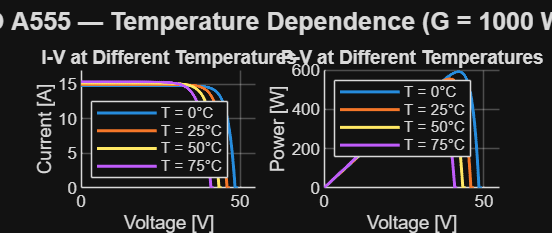


%% ========================================================================
%  4. TEMPERATURE & IRRADIANCE MODEL  (Sera et al. 2007)
%  ========================================================================

% --- 4a. Temperature sweep (1000 W/m²) ---
figure('Name', 'Temperature Dependence', 'Position', [50 50 1000 420]);
temps = [0 25 50 75];
colors = lines(length(temps));

subplot(1,2,1); hold on;
subplot(1,2,2); hold on;

for jj = 1:length(temps)
    [I_t, V_t, P_t] = pv_model_GT(ds, Rs, Rsh, A, 1000, temps(jj));
    subplot(1,2,1);
    plot(V_t, I_t, '-', 'Color', colors(jj,:), 'LineWidth', 1.5);
    subplot(1,2,2);
    plot(V_t, P_t, '-', 'Color', colors(jj,:), 'LineWidth', 1.5);
end

subplot(1,2,1);
xlabel('Voltage [V]'); ylabel('Current [A]');
title('I-V at Different Temperatures');
legend(arrayfun(@(t) sprintf('T = %d°C', t), temps, 'UniformOutput', false), ...
       'Location', 'southwest');
grid on; xlim([0 55]); ylim([0 17]);

subplot(1,2,2);
xlabel('Voltage [V]'); ylabel('Power [W]');
title('P-V at Different Temperatures');
legend(arrayfun(@(t) sprintf('T = %d°C', t), temps, 'UniformOutput', false), ...
       'Location', 'northwest');
grid on; xlim([0 55]);

sgtitle('AIKO A555 — Temperature Dependence (G = 1000 W/m²)', 'FontWeight', 'bold');


% --- 4b. Irradiance sweep (25 °C) ---
figure('Name', 'Irradiance Dependence', 'Position', [50 500 1000 420]);
irrs = [200 400 600 800 1000];
colors2 = lines(length(irrs));

subplot(1,2,1); hold on;
subplot(1,2,2); hold on;

fprintf('=== Irradiance Sweep (T = 25°C) ===\n');

=== Irradiance Sweep (T = 25°C) ===


for jj = 1:length(irrs)
    [I_g, V_g, P_g] = pv_model_GT(ds, Rs, Rsh, A, irrs(jj), 25);
    [Pmax_g, idx_g] = max(P_g);
    fprintf('G = %4d W/m²:  Isc = %.2f A,  Pmpp = %.1f W\n', irrs(jj), I_g(1), Pmax_g);

    subplot(1,2,1);
    plot(V_g, I_g, '-', 'Color', colors2(jj,:), 'LineWidth', 1.5);
    subplot(1,2,2);
    plot(V_g, P_g, '-', 'Color', colors2(jj,:), 'LineWidth', 1.5);
end

G =  200 W/m²:  Isc = 2.99 A,  Pmpp = 101.7 W
G =  400 W/m²:  Isc = 5.98 A,  Pmpp = 211.8 W
G =  600 W/m²:  Isc = 8.98 A,  Pmpp = 325.0 W
G =  800 W/m²:  Isc = 11.97 A,  Pmpp = 440.0 W
G = 1000 W/m²:  Isc = 14.96 A,  Pmpp = 556.5 W


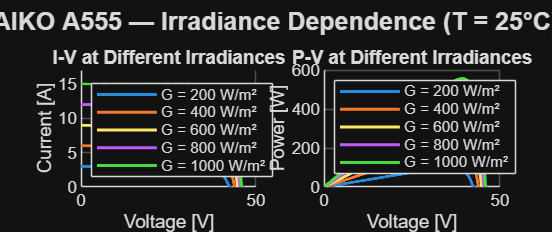


subplot(1,2,1);
xlabel('Voltage [V]'); ylabel('Current [A]');
title('I-V at Different Irradiances');
legend(arrayfun(@(g) sprintf('G = %d W/m²', g), irrs, 'UniformOutput', false), ...
       'Location', 'southwest');
grid on; xlim([0 50]); ylim([0 17]);

subplot(1,2,2);
xlabel('Voltage [V]'); ylabel('Power [W]');
title('P-V at Different Irradiances');
legend(arrayfun(@(g) sprintf('G = %d W/m²', g), irrs, 'UniformOutput', false), ...
       'Location', 'northwest');
grid on; xlim([0 50]);

sgtitle('AIKO A555 — Irradiance Dependence (T = 25°C)', 'FontWeight', 'bold');

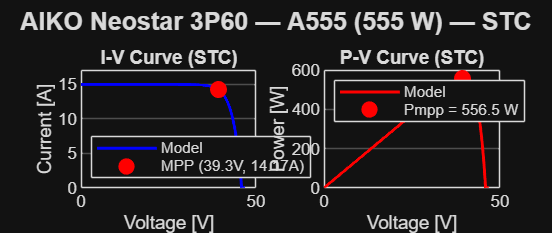


% --- 4c. STC I-V and P-V ---
figure('Name', 'STC Characteristics', 'Position', [50 950 1000 420]);

subplot(1,2,1);
plot(V_stc, I_stc, 'b-', 'LineWidth', 1.5); hold on;
plot(V_stc(idx), I_stc(idx), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
xlabel('Voltage [V]'); ylabel('Current [A]');
title('I-V Curve (STC)');
legend('Model', sprintf('MPP (%.1fV, %.2fA)', V_stc(idx), I_stc(idx)), ...
       'Location', 'southwest');
grid on; xlim([0 50]); ylim([0 17]);

subplot(1,2,2);
plot(V_stc, P_stc, 'r-', 'LineWidth', 1.5); hold on;
plot(V_stc(idx), Pmax_stc, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
xlabel('Voltage [V]'); ylabel('Power [W]');
title('P-V Curve (STC)');
legend('Model', sprintf('Pmpp = %.1f W', Pmax_stc), 'Location', 'northwest');
grid on; xlim([0 50]);

sgtitle('AIKO Neostar 3P60 — A555 (555 W) — STC', 'FontWeight', 'bold');


% --- 4d. NOCT verification ---
fprintf('\n=== NOCT Verification (800 W/m², ~45°C cell) ===\n');


=== NOCT Verification (800 W/m², ~45°C cell) ===


T_noct_cell = 45;
[I_n, V_n, P_n] = pv_model_GT(ds, Rs, Rsh, A, 800, T_noct_cell);
[Pmax_n, idx_n] = max(P_n);
Voc_n_idx = find(I_n > 0.01, 1, 'last');
fprintf('Pmpp model = %.1f W   (datasheet: 421 W)\n', Pmax_n);

Pmpp model = 416.2 W   (datasheet: 421 W)


fprintf('Vmpp model = %.2f V   (datasheet: 36.72 V)\n', V_n(idx_n));

Vmpp model = 36.66 V   (datasheet: 36.72 V)


fprintf('Impp model = %.2f A   (datasheet: 11.47 A)\n', I_n(idx_n));

Impp model = 11.35 A   (datasheet: 11.47 A)


if ~isempty(Voc_n_idx)
    fprintf('Voc  model = %.2f V   (datasheet: 43.55 V)\n', V_n(Voc_n_idx));
end

Voc  model = 43.34 V   (datasheet: 43.55 V)



%% ========================================================================
%  HELPER FUNCTIONS
%  ========================================================================

function I_out = solve_IV(V, Iph, I0, Rs, Rsh, nsVt)
% SOLVE_IV  Solve the implicit single-diode equation at each voltage.
%   I = Iph - I0*(exp((V+I*Rs)/nsVt) - 1) - (V+I*Rs)/Rsh
    I_out = zeros(size(V));
    opts = optimset('Display','off','TolX',1e-12);
    for kk = 1:length(V)
        Vk = V(kk);
        fun = @(Ik) Iph - I0*(exp((Vk + Ik*Rs)/nsVt) - 1) ...
                    - (Vk + Ik*Rs)/Rsh - Ik;
        I_guess = max(Iph - Vk/Rsh, 0);
        try
            I_out(kk) = fzero(fun, I_guess, opts);
        catch
            I_out(kk) = 0;
        end
    end
    I_out(I_out < 0) = 0;
end

function [I_out, V_out, P_out] = pv_model_GT(ds, Rs, Rsh, A, G, T_degC)
% PV_MODEL_GT  Compute I-V curve at irradiance G [W/m²] and temp T [°C].
%   Uses Sera et al. (2007) temperature/irradiance model:
%     - Isc, Voc shift with linear temperature coefficients
%     - I0(T) recomputed via Sera Eq. 29
%     - Iph scales linearly with irradiance

    q_ = 1.602176634e-19;
    k_ = 1.380649e-23;
    Ns   = ds.Ns;
    Tstc = ds.Tstc;
    T    = T_degC + 273.15;

    % Thermal voltage at operating temperature
    Vt_op = A * k_ * T / q_;
    nsVt  = Ns * Vt_op;

    % Temperature-adjusted Isc and Voc
    Isc_T = ds.Isc * (1 + ds.ki/100 * (T - Tstc));
    Voc_T = ds.Voc * (1 + ds.kv/100 * (T - Tstc));

    % I0 at temperature (Sera Eq. 29)
    Io_T = (Isc_T - (Voc_T - Isc_T*Rs)/Rsh) * exp(-Voc_T / nsVt);
    if Io_T <= 0
        Io_T = ds.Isc * exp(-ds.Voc / nsVt) * 1e-3;
    end

    % Iph at temperature (Sera Eq. 30)
    Iph_T = Io_T * exp(Voc_T / nsVt) + Voc_T / Rsh;

    % Irradiance scaling
    Iph_GT = Iph_T * (G / 1000);

    % Voc at irradiance (Newton-Raphson on Eq. 23)
    Voc_GT = max(Voc_T, 0.1);
    for nn = 1:50
        f_  = Iph_GT - Io_T * exp(Voc_GT / nsVt) - Voc_GT / Rsh;
        fp_ = -Io_T / nsVt * exp(Voc_GT / nsVt) - 1/Rsh;
        dV  = -f_ / fp_;
        Voc_GT = Voc_GT + dV;
        if abs(dV) < 1e-8, break; end
    end
    Voc_GT = max(Voc_GT, 0);

    % Solve full I-V
    V_out = linspace(0, Voc_GT * 1.02, 1000);
    I_out = solve_IV(V_out, Iph_GT, Io_T, Rs, Rsh, nsVt);
    P_out = V_out .* I_out;
end